% If you have the mean and variance you have the Gaussian distribution
% Generate data from 2D Gaussian distribution

% component1
mu1 = [1 2]; %mean
sigma1 = [ 3 .2;  % covariance matrix 
          .2  2];
m1 = 200;  % number of data points        

% component2
mu2 = [-1 -2];  % mean
sigma2 = [2 0;  % covariance matrix
          0 1];
m2 = 100;   % number of data points

% generate sameple points with the means and covarinace matrix above

% component1
R1 = chol(sigma1);  % Cholesky factorization -> covariance decomposition
X1 = randn(m1, 2) * R1; % generate bivariate normal numbers (size of data points)
X1 = X1 + repmat(mu1, size(X1, 1), 1);  % distribution with mean specified

% component2
R2 = chol(sigma2);
X2 = randn(m2, 2) * R2;
X2 = X2 + repmat(mu2, size(X2, 1), 1);

% combine component1 and component2
X = [X1; X2];

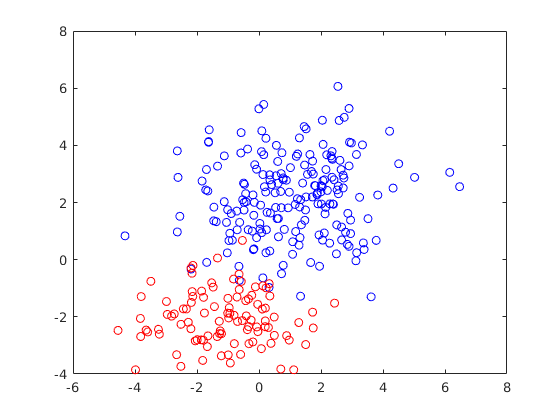

% Plot the data points and their pdfs (probability density function)

% Display the scatter plot of the two distribution
figure(1);

hold off;
plot(X1(:, 1), X1(:, 2), 'bo');
hold on;
plot(X2(:, 1), X2(:, 2), 'ro');


set(gcf,'color','white') % the figure is in white background


% create a matrix girdX (x,y coordinates) as the input values over the grid (range from -6 to 6)
addpath('GMMExample/*');

gridSize = 100;
u = linspace(-6, 6, gridSize);
[A B] = meshgrid(u, u);
gridX = [A(:), B(:)];
disp(gridX);

   -6.0000   -6.0000
   -6.0000   -5.8788
   -6.0000   -5.7576
   -6.0000   -5.6364
   -6.0000   -5.5152
   -6.0000   -5.3939
   -6.0000   -5.2727
   -6.0000   -5.1515
   -6.0000   -5.0303
   -6.0000   -4.9091
   -6.0000   -4.7879
   -6.0000   -4.6667
   -6.0000   -4.5455
   -6.0000   -4.4242
   -6.0000   -4.3030
   -6.0000   -4.1818
   -6.0000   -4.0606
   -6.0000   -3.9394
   -6.0000   -3.8182
   -6.0000   -3.6970
   -6.0000   -3.5758
   -6.0000   -3.4545
   -6.0000   -3.3333
   -6.0000   -3.2121
   -6.0000   -3.0909
   -6.0000   -2.9697
   -6.0000   -2.8485
   -6.0000   -2.7273
   -6.0000   -2.6061
   -6.0000   -2.4848
   -6.0000   -2.3636
   -6.0000   -2.2424
   -6.0000   -2.1212
   -6.0000   -2.0000
   -6.0000   -1.8788
   -6.0000   -1.7576
   -6.0000   -1.6364
   -6.0000   -1.5152
   -6.0000   -1.3939
   -6.0000   -1.2727
   -6.0000   -1.1515
   -6.0000   -1.0303
   -6.0000   -0.9091
   -6.0000   -0.7879
   -6.0000   -0.6667
   -6.0000   -0.5455
   -6.0000   -0.4242
   -6.0000   


z1 = gaussianND(gridX, mu1, sigma1);

Unrecognized function or variable 'gaussianND'.

z2 = gaussianND(gridX, mu2, sigma2);


Z1 = reshape(z1, gridSize, gridSize);
Z2 = reshape(z2, gridSize, gridSize);


[C, h] = contour(u, u, Z1);
[C, h] = contour(u, u, Z2);

axis([-6 6 -6 6])
title('Original Data and PDFs');